# Import data

opts = delimitedTextImportOptions("NumVariables", 10);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["track_id", "year", "month", "day", "hour", "i", "j", "lon", "lat", "msl"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
LabCandidates2019 = readtable("C:\Users\terri\Documents\MATLAB\ERA5Lab\2019_ERA5_Lab_Candidates.csv", opts);
clear opts

## Figure

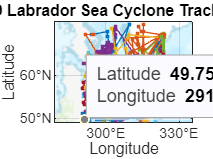


% Defining variables for the columns in the cyclone data 
% LabCandidatesT = table2array(LabCandidates);
% trackIDT = LabCandidatesT(:, 1);
% monthT = LabCandidatesT(:, [3 8 9]);
% dayT = LabCandidatesT(:, 4);
% hourT = LabCandidatesT(:, 5);
% lon1 = LabCandidatesT(:, 8);
% lat1 = LabCandidatesT(:, 9);
% n =  max(trackIDT);

i = max(LabCandidates2019.track_id);
for b = 0:i
    lat2 = LabCandidates2019.lat(LabCandidates2019.track_id == b);
    lon2 = LabCandidates2019.lon(LabCandidates2019.track_id == b);
    geoplot(lat2,lon2,'.-')
%     geolimits([45 70],[290 324])
    hold on
end
geobasemap('topographic')
title('2019 Labrador Sea Cyclone Tracks- ERA5')



% for a specific month, define a new table/array that's only the section 
% of the table for that month, including lat/lon
% geoplot(LabCandidates,"lat","lon",'.-')
% geobasemap("colorterrain")
% title('2015 Cyclone Tracks- test')

% Making a track figure for January storms
% for LabCandidates.month = 1
%     for day = 1:3
%         geoplot(lat,lon,'.-')
%         hold on
%     end
%     geobasemap('colorterrain')
%     title('January 2015 Cyclone Tracks')
% end

## Exporting the figure

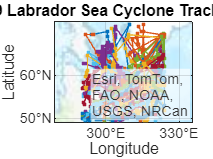

exportgraphics(gca,"LabERA52019.png","Resolution",300)

## Geodensityplot

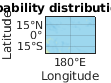

latAll = LabCandidates2019.lat;
lonAll = LabCandidates2019.lon;
geodensityplot(latAll,lonAll)
geobasemap("bluegreen")
title('Cumulative probability distribution of cyclones, 2015')

## Monthly plots

% for b = 0:i
% for LabCandidatesT
%     switch monthT 
%         case LabCandidates.month == 1
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 2
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 3
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 4
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 5
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 6
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 7
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 8
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 9
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 10
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 11
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 12
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%     end
% end

SWITCH expression must be a scalar or a character vector.

## Defining tables for each month's data

Jan = LabCandidates2019(LabCandidates2019.month == 1, :);
Feb = LabCandidates2019(LabCandidates2019.month == 2, :);
Mar = LabCandidates2019(LabCandidates2019.month == 3, :);
Apr = LabCandidates2019(LabCandidates2019.month == 4, :);
May = LabCandidates2019(LabCandidates2019.month == 5, :);
Jun = LabCandidates2019(LabCandidates2019.month == 6, :);
Jul = LabCandidates2019(LabCandidates2019.month == 7, :);
Aug = LabCandidates2019(LabCandidates2019.month == 8, :);
Sep = LabCandidates2019(LabCandidates2019.month == 9, :);
Oct = LabCandidates2019(LabCandidates2019.month == 10, :);
Nov = LabCandidates2019(LabCandidates2019.month == 11, :);
Dec = LabCandidates2019(LabCandidates2019.month == 12, :);

## Making monthly plots

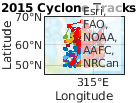

% k = max(Jan.track_id);
% for d = 0:k
%     latj = Jan.lat(Jan.track_id == d);
%     lonj = Jan.lon(Jan.track_id == d);
%     geoplot(latj,lonj,'.- red')
%     geolimits([45 70],[290 324])
%     hold on
% end
% geobasemap('topographic')
% title('Jan 2015 Cyclone Tracks in ERA5')

cc = orderedcolors("gem12");

dd = orderedcolors("reef");
i = max(LabCandidates2019.track_id);
for b = 0:i
    latJan = Jan.lat(Jan.track_id == b);
    lonJan = Jan.lon(Jan.track_id == b);
    geoplot(latJan,lonJan,colororder(cc(1)))
    hold on
    latFeb = Feb.lat(Feb.track_id == b);
    lonFeb = Feb.lon(Feb.track_id == b);
    geoplot(latFeb,lonFeb,'.-')
    hold on 
    latMar = Mar.lat(Mar.track_id == b);
    lonMar = Mar.lon(Mar.track_id == b);
    geoplot(latMar,lonMar,'.-')
    hold on 
    latApr = Apr.lat(Apr.track_id == b);
    lonApr = Apr.lon(Apr.track_id == b);
    geoplot(latApr,lonApr,'.-')
    hold on 
    latMay = May.lat(May.track_id == b);
    lonMay = May.lon(May.track_id == b);
    geoplot(latMay,lonMay,'.-')
    hold on 
    latJun = Jun.lat(Jun.track_id == b);
    lonJun = Jun.lon(Jun.track_id == b);
    geoplot(latJun,lonJun,'.-')
    hold on 
    latJul = Jul.lat(Jul.track_id == b);
    lonJul = Jul.lon(Jul.track_id == b);
    geoplot(latJul,lonJul,'.-')
    hold on 
    latAug = Aug.lat(Aug.track_id == b);
    lonAug = Aug.lon(Aug.track_id == b);
    geoplot(latAug,lonAug,'.-')
    hold on 
    latSep = Sep.lat(Sep.track_id == b);
    lonSep = Sep.lon(Sep.track_id == b);
    geoplot(latSep,lonSep,'.-')
    hold on 
    latOct = Oct.lat(Oct.track_id == b);
    lonOct = Oct.lon(Oct.track_id == b);
    geoplot(latOct,lonOct,'.-')
    hold on 
    latNov = Nov.lat(Nov.track_id == b);
    lonNov = No.lon(Nov.track_id == b);
    geoplot(latNov,lonNov,'.-')
    hold on 
    latDec = Dec.lat(Dec.track_id == b);
    lonDec = Dec.lon(Dec.track_id == b);
    geoplot(latDec,lonDec,'.-')
    hold on 
end
geobasemap('topographic')
title('2002 Cyclone Tracks in ERA5 Labrador Sea (3h)')


## Plotting a single track

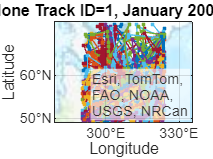

latx = LabCandidates2002.lat(LabCandidates2002.track_id == 0);
lonx = LabCandidates2002.lon(LabCandidates2002.track_id == 0);
geoplot(latx,lonx,'.-')
geobasemap('topographic')
title('Cyclone Track ID=1, January 2002 (ERA5)')